# 做2021/5/19-2022/5/18 的VaR预测

方法对比：Historical simulation, mean-variance

We use forecast volatilites to estimate VaR.

%% load data
clear,clc
database=load("VolFcst_normal_SP500_size750_20220803.mat");
D=readtable("SP500_0608.xlsx");
forecast_index=D.Date>=datetime(2021,5,18);
SaveVaRNameSuffix='SP500_20220805';
results_folder=['results_',SaveVaRNameSuffix];
SaveTxtName=strcat(results_folder,'/','VaR_',SaveVaRNameSuffix,'.txt');
[SUCCESS,MESSAGE,MESSAGEID]=mkdir(results_folder);
addpath(results_folder);
% Model_Name={'Historical simulation','Variance-covariance','GARCH','CPGARCH','CPGARCHiteration',...
%     'GJR','CPGJR','CPGJRiteration','RSGARCH','CPRSGARCH','CPRSGARCHiteration',...
%     'HAR','CPHAR','CPHARiteration','Variance-covariance','GARCH','CPGARCH','CPGARCHiteration',...
%     'GJR','CPGJR','CPGJRiteration','RSGARCH','CPRSGARCH','CPRSGARCHiteration',...
%     'HAR','CPHAR','CPHARiteration'};
CL_Name={'99.7\5%','99.5\%','99\%','97.5\%','95\%','92.5\%','90\%'};

Preparation

logRet=D.Return(forecast_index);
TimeLine=D.Date(forecast_index);
T=length(logRet); % forecast window
ConfidenceLevel=[0.25 0.5 1 2.5 5 7.5 10]*0.01;
FigureVaRIndex=[3,5,7];% use FigureVaRIndex of ConfidenceLevel to figure VaR

% Writing header
ftxt=fopen(SaveTxtName,'w+');
n_row = size(T,1);
n_col = size(CL_Name,2);
col_spec = [];
for c = 1:n_col, col_spec = [col_spec 'l']; end %#ok<AGROW> 
col_names = strjoin(CL_Name, ' & ');
col_spec = ['l' col_spec];
col_names = ['& ' col_names];
fprintf(ftxt,'\\begin{tabular}{%s}\n', col_spec);
fprintf(ftxt,'%s \\\\ \n', col_names);
fprintf(ftxt,'\\hline \n');
fclose(ftxt);

% Writing middle

## 历史模拟法

hVaR = zeros(size(logRet,1),length(ConfidenceLevel)); % historical simulation
for i = 1 : T
    historic_return = D.Return(find(forecast_index,1)+i-251:find(forecast_index,1)+i-2);
    %历史模拟法
    confidence = prctile(historic_return, ConfidenceLevel*100);
    hVaR(i, :) = confidence;
end

% ftxt=fopen(SaveTxtName,'a+');fprintf(ftxt,'历史模拟法. \n');fclose(ftxt);
Output_hist=tableVaRPredict(hVaR,logRet,ConfidenceLevel)%历史模拟法

Output_hist = 4×7 table
                        CL0.0025    CL0.005    CL0.01     CL0.025    CL0.05     CL0.075    CL0.1 
                        ________    _______    _______    _______    _______    _______    ______

    Confidence level     0.0025       0.005       0.01      0.025       0.05      0.075       0.1
    Failures                  5           6          9         13         21         32        45
    Kupiec Test           11.95        9.22       9.97       5.45       4.74       7.91     13.82
    Significance        0.99945     0.99761    0.99841    0.98043    0.97053    0.99508    0.9998


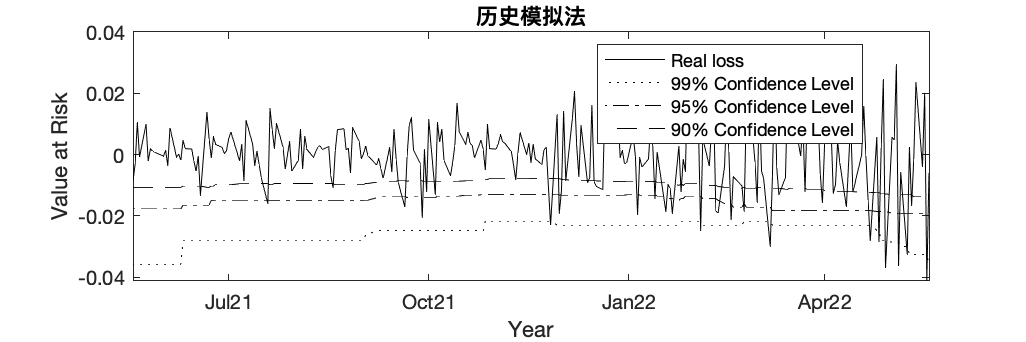

ftxt=fopen(SaveTxtName,'a+');
fprintf(ftxt,'\n');
fprintf(ftxt,'Historical simulation &');
line2latex(Output_hist(3,:),ftxt)
fclose(ftxt);
figureVaR(hVaR(:,FigureVaRIndex),logRet,TimeLine);
title('历史模拟法')
set(gcf,'Position',[500 500 900 300]);
saveas(gcf,[results_folder,'/VaR_Historical.png'])

## Variance-covariance normal 分布

pVaR_normal = zeros(size(logRet,1),length(ConfidenceLevel)); % variance-covariance normal distribution
for i = 1 : T
    historic_return = D.Return(find(forecast_index,1)+i-251:find(forecast_index,1)+i-2);
    % innovation normal distributed
    pVaR_normal(i, :) = norminv(ConfidenceLevel,mean(historic_return),std(historic_return));    
end
Output_vacov_normal=tableVaRPredict(pVaR_normal,logRet,ConfidenceLevel)% normal distribution

Output_vacov_normal = 4×7 table
                        CL0.0025    CL0.005    CL0.01    CL0.025    CL0.05     CL0.075     CL0.1 
                        ________    _______    ______    _______    _______    _______    _______

    Confidence level     0.0025      0.005      0.01       0.025       0.05      0.075        0.1
    Failures                  9         10        15          19         24         33         38
    Kupiec Test           31.21      24.05     28.88        16.9       8.39       9.09       6.01
    Significance              1          1         1     0.99996    0.99623    0.99743    0.98577


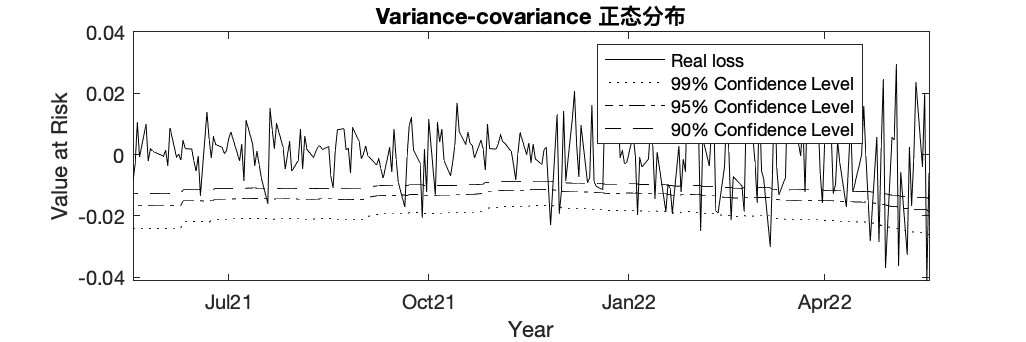

ftxt=fopen(SaveTxtName,'a+');
fprintf(ftxt,'\n');
fprintf(ftxt,'Variance-covariance &');
line2latex(Output_vacov_normal(3,:),ftxt)
fclose(ftxt);
figureVaR(pVaR_normal(:,FigureVaRIndex),logRet,TimeLine);
title('Variance-covariance 正态分布')
set(gcf,'Position',[500 500 900 300]);
saveas(gcf,[results_folder,'/VaR_vacov_normal.png'])

## GARCH normal VaR

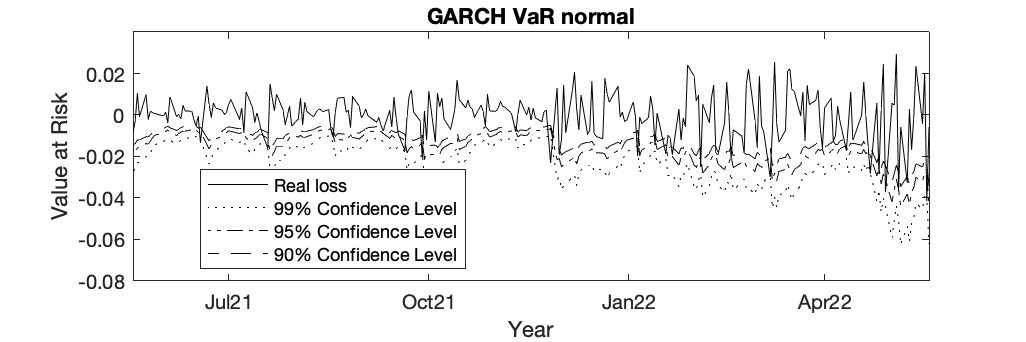

Model_Name='GARCH';
vf=database.vf_GARCH;
Output_GARCH=report_VaR(vf,logRet,TimeLine,ConfidenceLevel,D,forecast_index,FigureVaRIndex,SaveTxtName,Model_Name);
ftxt=fopen(SaveTxtName,'a+');
fprintf(ftxt,'\n');
fprintf(ftxt,[Model_Name,' & ']);
line2latex(Output_GARCH.Table_normal(3,:),ftxt)
fclose(ftxt);
figureVaR(Output_GARCH.VaR_normal(:,FigureVaRIndex),logRet,TimeLine);
title([Model_Name,' VaR normal'])
set(gcf,'Position',[500 500 900 300]);
saveas(gcf,[results_folder,'/VaR_',Model_Name,'_normal.png'])

## CPGARCH normal VaR

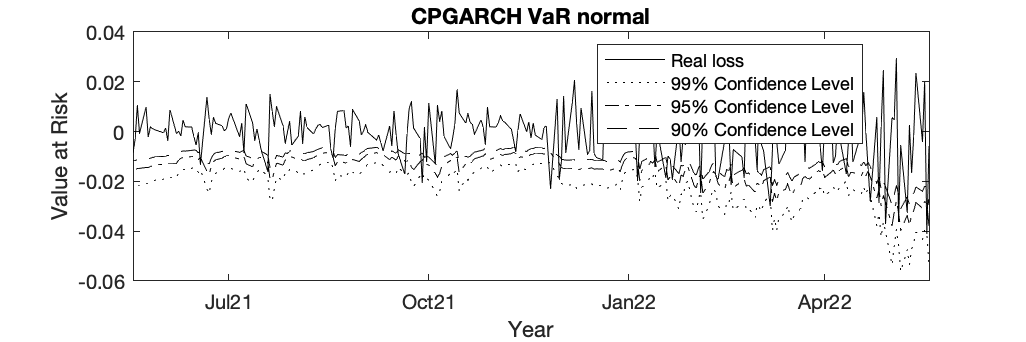

Model_Name='CPGARCH';
vf=database.vf_CPGARCH;
Output_CPGARCH=report_VaR(vf,logRet,TimeLine,ConfidenceLevel,D,forecast_index,FigureVaRIndex,SaveTxtName,Model_Name);
ftxt=fopen(SaveTxtName,'a+');
fprintf(ftxt,'\n');
fprintf(ftxt,[Model_Name,' & ']);
line2latex(Output_CPGARCH.Table_normal(3,:),ftxt)
fclose(ftxt);
figureVaR(Output_CPGARCH.VaR_normal(:,FigureVaRIndex),logRet,TimeLine);
title([Model_Name,' VaR normal'])
set(gcf,'Position',[500 500 900 300]);
saveas(gcf,[results_folder,'/VaR_',Model_Name,'_normal.png'])

## CPGARCHiteration normal VaR

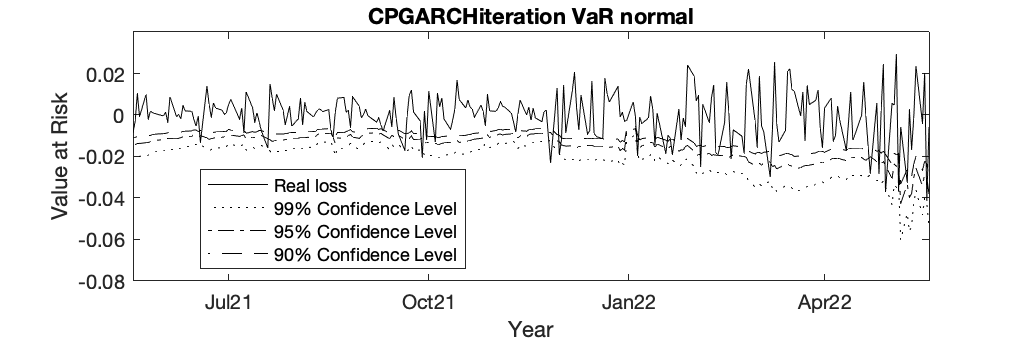

Model_Name='CPGARCHiteration';
vf=database.vf_CPGARCHiteration;
Output_CPGARCHiteration=report_VaR(vf,logRet,TimeLine,ConfidenceLevel,D,forecast_index,FigureVaRIndex,SaveTxtName,Model_Name);
ftxt=fopen(SaveTxtName,'a+');
fprintf(ftxt,'\n');
fprintf(ftxt,[Model_Name,' & ']);
line2latex(Output_CPGARCHiteration.Table_normal(3,:),ftxt)
fclose(ftxt);
figureVaR(Output_CPGARCHiteration.VaR_normal(:,FigureVaRIndex),logRet,TimeLine);
title([Model_Name,' VaR normal'])
set(gcf,'Position',[500 500 900 300]);
saveas(gcf,[results_folder,'/VaR_',Model_Name,'_normal.png'])

## GJR normal VaR

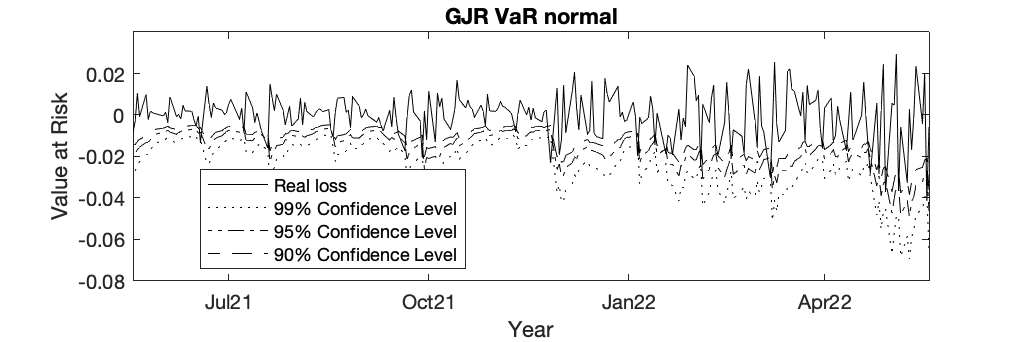

Model_Name='GJR';
vf=database.vf_GJR;
Output_GJR=report_VaR(vf,logRet,TimeLine,ConfidenceLevel,D,forecast_index,FigureVaRIndex,SaveTxtName,Model_Name);
ftxt=fopen(SaveTxtName,'a+');
fprintf(ftxt,'\n');
fprintf(ftxt,[Model_Name,' & ']);
line2latex(Output_GJR.Table_normal(3,:),ftxt)
fclose(ftxt);
figureVaR(Output_GJR.VaR_normal(:,FigureVaRIndex),logRet,TimeLine);
title([Model_Name,' VaR normal'])
set(gcf,'Position',[500 500 900 300]);
saveas(gcf,[results_folder,'/VaR_',Model_Name,'_normal.png'])

## CPGJR normal VaR

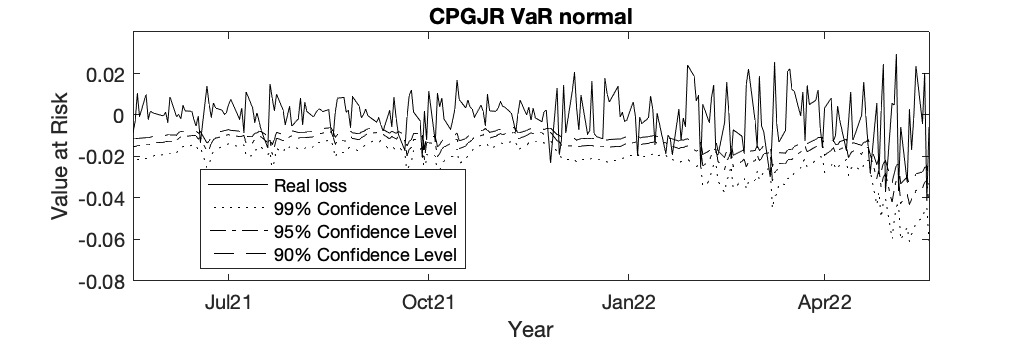

Model_Name='CPGJR';
vf=database.vf_CPGJR;
Output_CPGJR=report_VaR(vf,logRet,TimeLine,ConfidenceLevel,D,forecast_index,FigureVaRIndex,SaveTxtName,Model_Name);
ftxt=fopen(SaveTxtName,'a+');
fprintf(ftxt,'\n');
fprintf(ftxt,[Model_Name,' & ']);
line2latex(Output_CPGJR.Table_normal(3,:),ftxt)
fclose(ftxt);
figureVaR(Output_CPGJR.VaR_normal(:,FigureVaRIndex),logRet,TimeLine);
title([Model_Name,' VaR normal'])
set(gcf,'Position',[500 500 900 300]);
saveas(gcf,[results_folder,'/VaR_',Model_Name,'_normal.png'])

## CPGJRiteration normal VaR

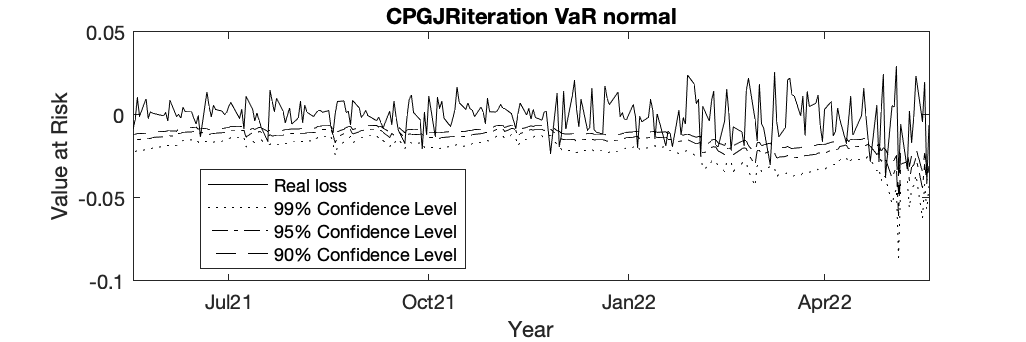

Model_Name='CPGJRiteration';
vf=database.vf_CPGJRiteration;
Output_CPGJRiteration=report_VaR(vf,logRet,TimeLine,ConfidenceLevel,D,forecast_index,FigureVaRIndex,SaveTxtName,Model_Name);
ftxt=fopen(SaveTxtName,'a+');
fprintf(ftxt,'\n');
fprintf(ftxt,[Model_Name,' & ']);
line2latex(Output_CPGJRiteration.Table_normal(3,:),ftxt)
fclose(ftxt);
figureVaR(Output_CPGJRiteration.VaR_normal(:,FigureVaRIndex),logRet,TimeLine);
title([Model_Name,' VaR normal'])
set(gcf,'Position',[500 500 900 300]);
saveas(gcf,[results_folder,'/VaR_',Model_Name,'_normal.png'])

## RSGARCH normal VaR

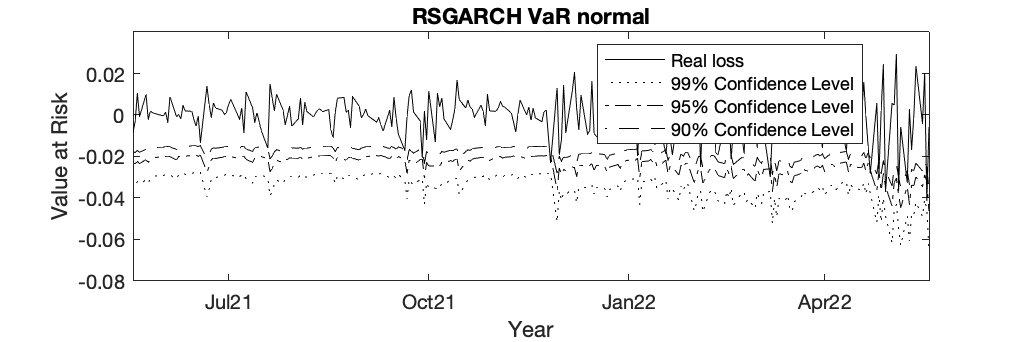

Model_Name='RSGARCH';
vf=database.vf_RSGARCH;
Output_RSGARCH=report_VaR(vf,logRet,TimeLine,ConfidenceLevel,D,forecast_index,FigureVaRIndex,SaveTxtName,Model_Name);
ftxt=fopen(SaveTxtName,'a+');
fprintf(ftxt,'\n');
fprintf(ftxt,[Model_Name,' & ']);
line2latex(Output_RSGARCH.Table_normal(3,:),ftxt)
fclose(ftxt);
figureVaR(Output_RSGARCH.VaR_normal(:,FigureVaRIndex),logRet,TimeLine);
title([Model_Name,' VaR normal'])
set(gcf,'Position',[500 500 900 300]);
saveas(gcf,[results_folder,'/VaR_',Model_Name,'_normal.png'])

## CPRSGARCH normal VaR

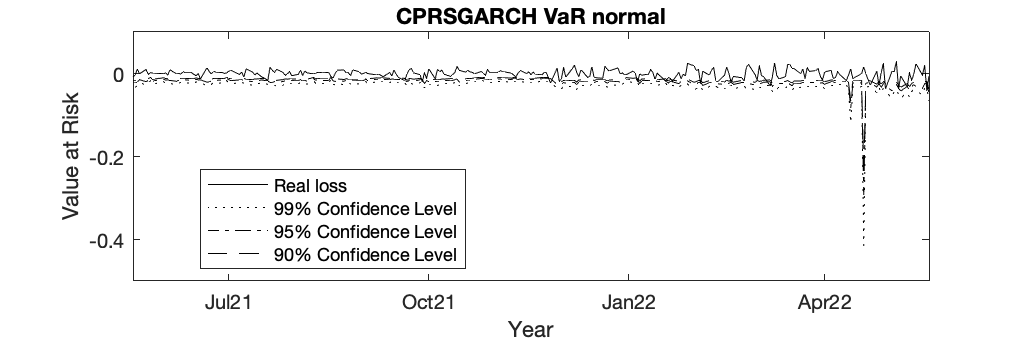

Model_Name='CPRSGARCH';
vf=database.vf_CPRSGARCH;
Output_CPRSGARCH=report_VaR(vf,logRet,TimeLine,ConfidenceLevel,D,forecast_index,FigureVaRIndex,SaveTxtName,Model_Name);
ftxt=fopen(SaveTxtName,'a+');
fprintf(ftxt,'\n');
fprintf(ftxt,[Model_Name,' & ']);
line2latex(Output_CPRSGARCH.Table_normal(3,:),ftxt)
fclose(ftxt);
figureVaR(Output_CPRSGARCH.VaR_normal(:,FigureVaRIndex),logRet,TimeLine);
title([Model_Name,' VaR normal'])
set(gcf,'Position',[500 500 900 300]);
saveas(gcf,[results_folder,'/VaR_',Model_Name,'_normal.png'])

## CPRSGARCHiteration normal VaR

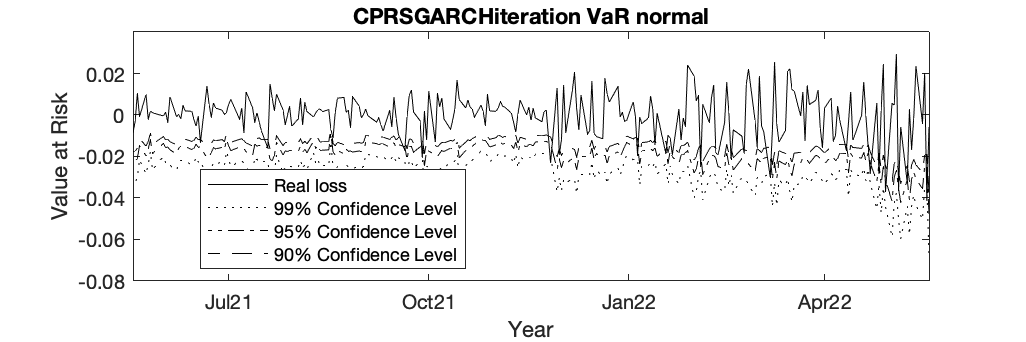

Model_Name='CPRSGARCHiteration';
vf=database.vf_CPRSGARCHiteration;
Output_CPRSGARCHiteration=report_VaR(vf,logRet,TimeLine,ConfidenceLevel,D,forecast_index,FigureVaRIndex,SaveTxtName,Model_Name);
ftxt=fopen(SaveTxtName,'a+');
fprintf(ftxt,'\n');
fprintf(ftxt,[Model_Name,' & ']);
line2latex(Output_CPRSGARCHiteration.Table_normal(3,:),ftxt)
fclose(ftxt);
figureVaR(Output_CPRSGARCHiteration.VaR_normal(:,FigureVaRIndex),logRet,TimeLine);
title([Model_Name,' VaR normal'])
set(gcf,'Position',[500 500 900 300]);
saveas(gcf,[results_folder,'/VaR_',Model_Name,'_normal.png'])

## HAR normal VaR

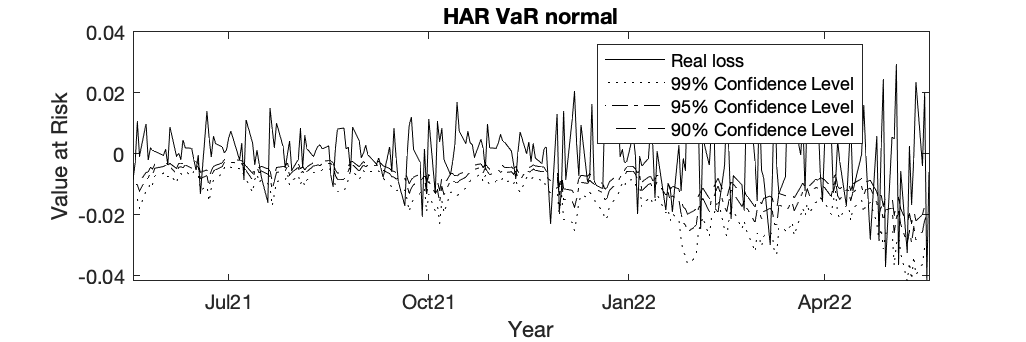

Model_Name='HAR';
vf=database.vf_HAR;
Output_HAR=report_VaR(vf,logRet,TimeLine,ConfidenceLevel,D,forecast_index,FigureVaRIndex,SaveTxtName,Model_Name);
ftxt=fopen(SaveTxtName,'a+');
fprintf(ftxt,'\n');
fprintf(ftxt,[Model_Name,' & ']);
line2latex(Output_HAR.Table_normal(3,:),ftxt)
fclose(ftxt);
figureVaR(Output_HAR.VaR_normal(:,FigureVaRIndex),logRet,TimeLine);
title([Model_Name,' VaR normal'])
set(gcf,'Position',[500 500 900 300]);
saveas(gcf,[results_folder,'/VaR_',Model_Name,'_normal.png'])

## CPHAR normal VaR

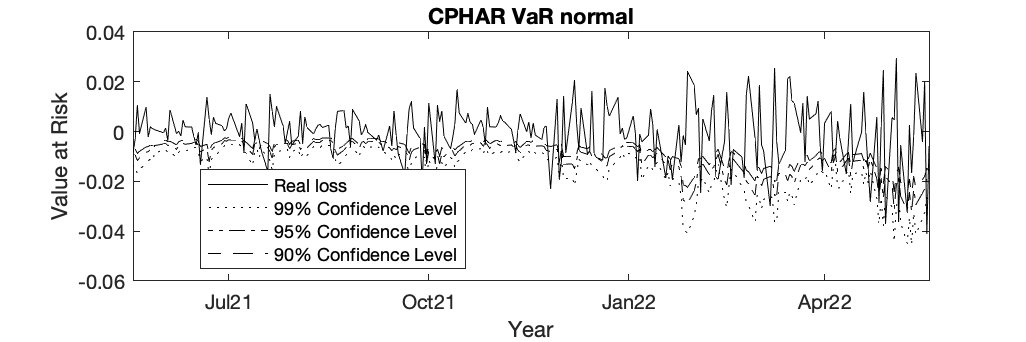

Model_Name='CPHAR';
vf=database.vf_CPHAR;
Output_CPHAR=report_VaR(vf,logRet,TimeLine,ConfidenceLevel,D,forecast_index,FigureVaRIndex,SaveTxtName,Model_Name);
ftxt=fopen(SaveTxtName,'a+');
fprintf(ftxt,'\n');
fprintf(ftxt,[Model_Name,' & ']);
line2latex(Output_CPHAR.Table_normal(3,:),ftxt)
fclose(ftxt);
figureVaR(Output_CPHAR.VaR_normal(:,FigureVaRIndex),logRet,TimeLine);
title([Model_Name,' VaR normal'])
set(gcf,'Position',[500 500 900 300]);
saveas(gcf,[results_folder,'/VaR_',Model_Name,'_normal.png'])

## CPHARiteration normal VaR

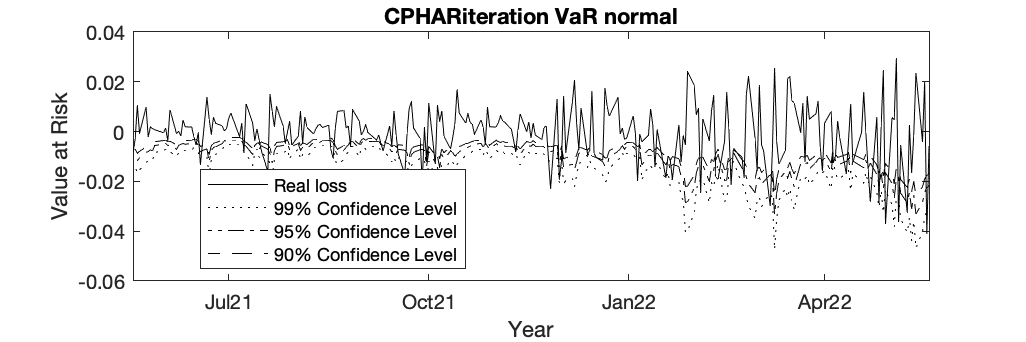

Model_Name='CPHARiteration';
vf=database.vf_CPHARiteration;
Output_CPHARiteration=report_VaR(vf,logRet,TimeLine,ConfidenceLevel,D,forecast_index,FigureVaRIndex,SaveTxtName,Model_Name);
ftxt=fopen(SaveTxtName,'a+');
fprintf(ftxt,'\n');
fprintf(ftxt,[Model_Name,' & ']);
line2latex(Output_CPHARiteration.Table_normal(3,:),ftxt)
fclose(ftxt);
figureVaR(Output_CPHARiteration.VaR_normal(:,FigureVaRIndex),logRet,TimeLine);
title([Model_Name,' VaR normal'])
set(gcf,'Position',[500 500 900 300]);
saveas(gcf,[results_folder,'/VaR_',Model_Name,'_normal.png'])

## Variance-covariance t分布

pVaR_t = zeros(size(logRet,1),length(ConfidenceLevel));% variance-covariance t distribution
for i = 1 : T
    historic_return = D.Return(find(forecast_index,1)+i-251:find(forecast_index,1)+i-2);
    % innovation student-t distributed
    fit_data=fitdist(historic_return,"tLocationScale");
    pVaR_t(i, :) = tinv(ConfidenceLevel,fit_data.nu)*fit_data.sigma+fit_data.mu;
end
Output_vacov_t=tableVaRPredict(pVaR_t,logRet,ConfidenceLevel)% student-t distribution

Output_vacov_t = 4×7 table
                        CL0.0025    CL0.005    CL0.01     CL0.025    CL0.05     CL0.075    CL0.1 
                        ________    _______    _______    _______    _______    _______    ______

    Confidence level     0.0025       0.005       0.01      0.025       0.05      0.075       0.1
    Failures                  3           8         10         19         26         37        45
    Kupiec Test            4.59       16.11      12.65       16.9      11.29      14.47     13.82
    Significance        0.96784     0.99994    0.99962    0.99996    0.99922    0.99986    0.9998


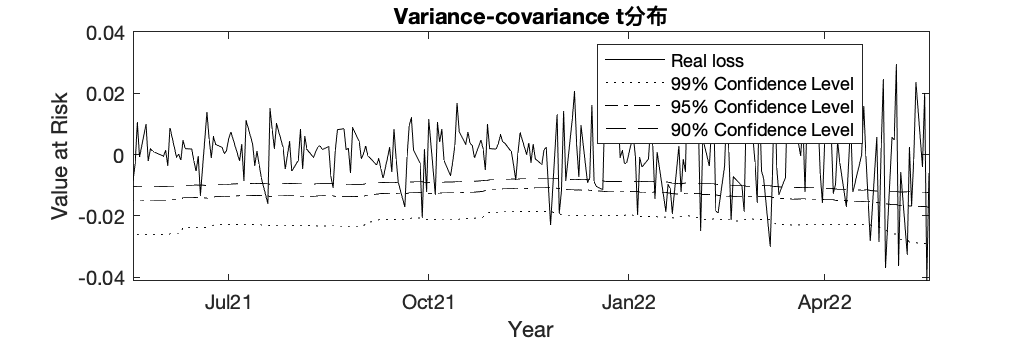

ftxt=fopen(SaveTxtName,'a+');
fprintf(ftxt,'\n');
fprintf(ftxt,'Variance-covariance &');
line2latex(Output_vacov_t(3,:),ftxt)
fclose(ftxt);
figureVaR(pVaR_t(:,FigureVaRIndex),logRet,TimeLine);
title('Variance-covariance t分布')
set(gcf,'Position',[500 500 900 300]);
saveas(gcf,[results_folder,'/VaR_vacov_t.png'])

## GARCH t VaR

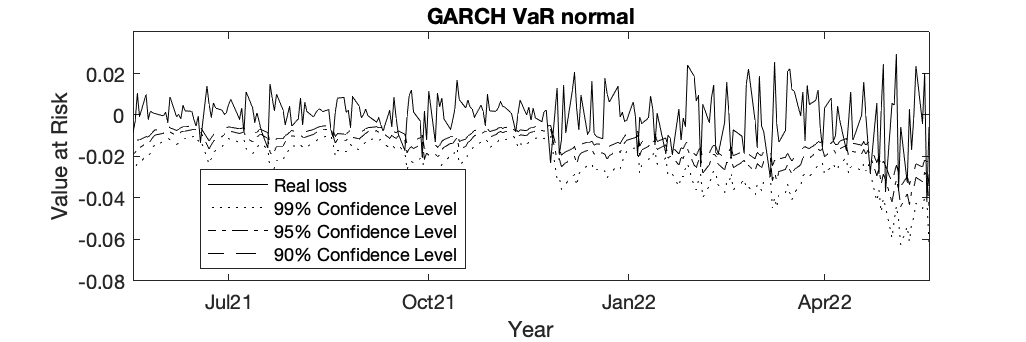

Model_Name='GARCH';
ftxt=fopen(SaveTxtName,'a+');
fprintf(ftxt,'\n');
fprintf(ftxt,[Model_Name,' & ']);
line2latex(Output_GARCH.Table_t(3,:),ftxt)
fclose(ftxt);
figureVaR(Output_GARCH.VaR_normal(:,FigureVaRIndex),logRet,TimeLine);
title([Model_Name,' VaR normal'])
set(gcf,'Position',[500 500 900 300]);
saveas(gcf,[results_folder,'/VaR_',Model_Name,'_t.png'])

## CPGARCH t VaR

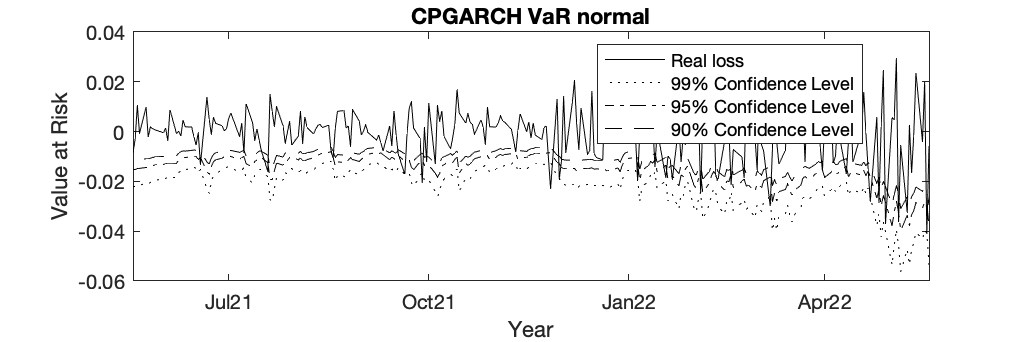

Model_Name='CPGARCH';
ftxt=fopen(SaveTxtName,'a+');
fprintf(ftxt,'\n');
fprintf(ftxt,[Model_Name,' & ']);
line2latex(Output_CPGARCH.Table_t(3,:),ftxt)
fclose(ftxt);
figureVaR(Output_CPGARCH.VaR_normal(:,FigureVaRIndex),logRet,TimeLine);
title([Model_Name,' VaR normal'])
set(gcf,'Position',[500 500 900 300]);
saveas(gcf,[results_folder,'/VaR_',Model_Name,'_t.png'])

## CPGARCHiteration t VaR

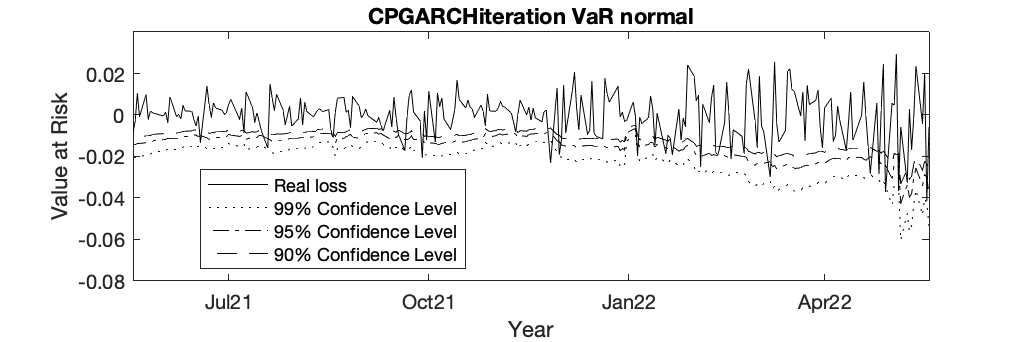

Model_Name='CPGARCHiteration';
ftxt=fopen(SaveTxtName,'a+');
fprintf(ftxt,'\n');
fprintf(ftxt,[Model_Name,' & ']);
line2latex(Output_CPGARCHiteration.Table_t(3,:),ftxt)
fclose(ftxt);
figureVaR(Output_CPGARCHiteration.VaR_normal(:,FigureVaRIndex),logRet,TimeLine);
title([Model_Name,' VaR normal'])
set(gcf,'Position',[500 500 900 300]);
saveas(gcf,[results_folder,'/VaR_',Model_Name,'_t.png'])

## GJR t VaR

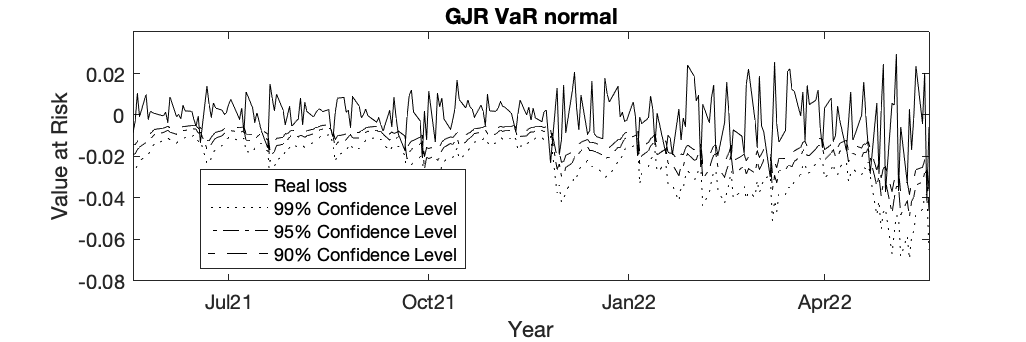

Model_Name='GJR';
ftxt=fopen(SaveTxtName,'a+');
fprintf(ftxt,'\n');
fprintf(ftxt,[Model_Name,' & ']);
line2latex(Output_GJR.Table_t(3,:),ftxt)
fclose(ftxt);
figureVaR(Output_GJR.VaR_normal(:,FigureVaRIndex),logRet,TimeLine);
title([Model_Name,' VaR normal'])
set(gcf,'Position',[500 500 900 300]);
saveas(gcf,[results_folder,'/VaR_',Model_Name,'_t.png'])

## CPGJR t VaR

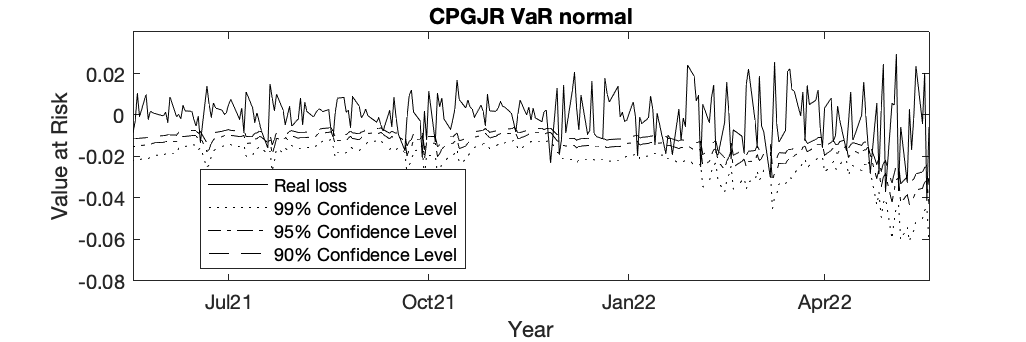

Model_Name='CPGJR';
ftxt=fopen(SaveTxtName,'a+');
fprintf(ftxt,'\n');
fprintf(ftxt,[Model_Name,' & ']);
line2latex(Output_CPGJR.Table_t(3,:),ftxt)
fclose(ftxt);
figureVaR(Output_CPGJR.VaR_normal(:,FigureVaRIndex),logRet,TimeLine);
title([Model_Name,' VaR normal'])
set(gcf,'Position',[500 500 900 300]);
saveas(gcf,[results_folder,'/VaR_',Model_Name,'_t.png'])

## CPGJRiteration t VaR

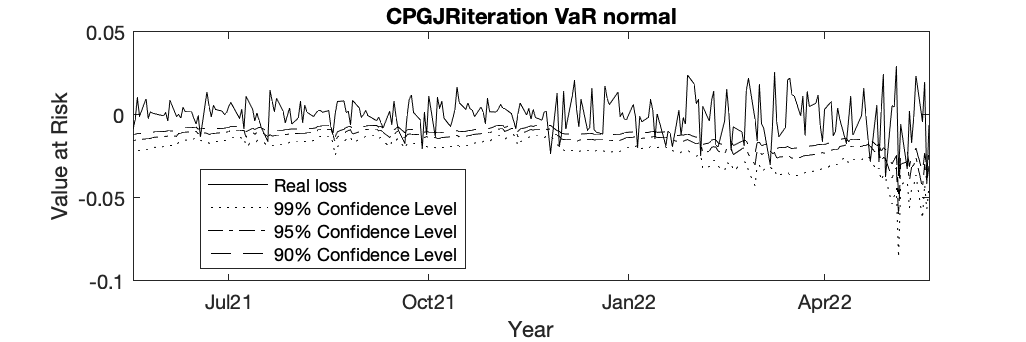

Model_Name='CPGJRiteration';
ftxt=fopen(SaveTxtName,'a+');
fprintf(ftxt,'\n');
fprintf(ftxt,[Model_Name,' & ']);
line2latex(Output_CPGJRiteration.Table_t(3,:),ftxt)
fclose(ftxt);
figureVaR(Output_CPGJRiteration.VaR_normal(:,FigureVaRIndex),logRet,TimeLine);
title([Model_Name,' VaR normal'])
set(gcf,'Position',[500 500 900 300]);
saveas(gcf,[results_folder,'/VaR_',Model_Name,'_t.png'])

## RSGARCH t VaR

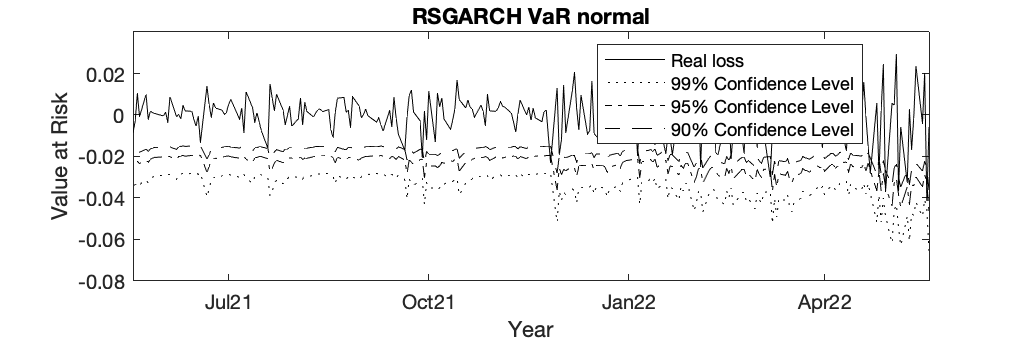

Model_Name='RSGARCH';
ftxt=fopen(SaveTxtName,'a+');
fprintf(ftxt,'\n');
fprintf(ftxt,[Model_Name,' & ']);
line2latex(Output_RSGARCH.Table_t(3,:),ftxt)
fclose(ftxt);
figureVaR(Output_RSGARCH.VaR_normal(:,FigureVaRIndex),logRet,TimeLine);
title([Model_Name,' VaR normal'])
set(gcf,'Position',[500 500 900 300]);
saveas(gcf,[results_folder,'/VaR_',Model_Name,'_t.png'])

## CPRSGARCH t VaR

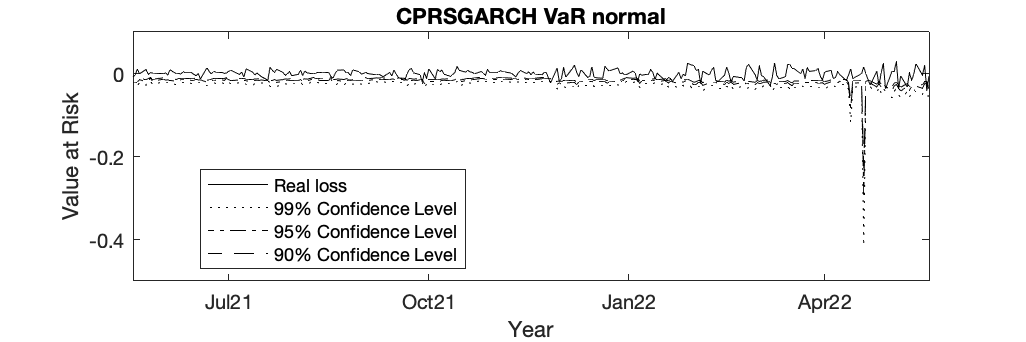

Model_Name='CPRSGARCH';
ftxt=fopen(SaveTxtName,'a+');
fprintf(ftxt,'\n');
fprintf(ftxt,[Model_Name,' & ']);
line2latex(Output_CPRSGARCH.Table_t(3,:),ftxt)
fclose(ftxt);
figureVaR(Output_CPRSGARCH.VaR_normal(:,FigureVaRIndex),logRet,TimeLine);
title([Model_Name,' VaR normal'])
set(gcf,'Position',[500 500 900 300]);
saveas(gcf,[results_folder,'/VaR_',Model_Name,'_t.png'])

## CPRSGARCHiteration t VaR

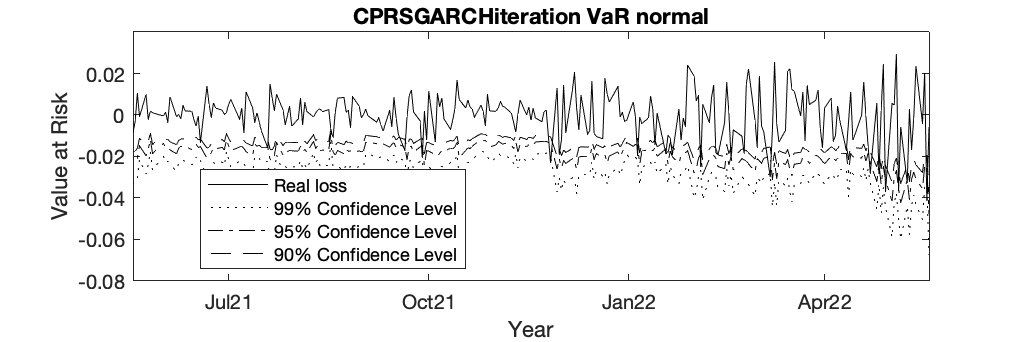

Model_Name='CPRSGARCHiteration';
ftxt=fopen(SaveTxtName,'a+');
fprintf(ftxt,'\n');
fprintf(ftxt,[Model_Name,' & ']);
line2latex(Output_CPRSGARCHiteration.Table_t(3,:),ftxt)
fclose(ftxt);
figureVaR(Output_CPRSGARCHiteration.VaR_normal(:,FigureVaRIndex),logRet,TimeLine);
title([Model_Name,' VaR normal'])
set(gcf,'Position',[500 500 900 300]);
saveas(gcf,[results_folder,'/VaR_',Model_Name,'_t.png'])

## HAR tVaR

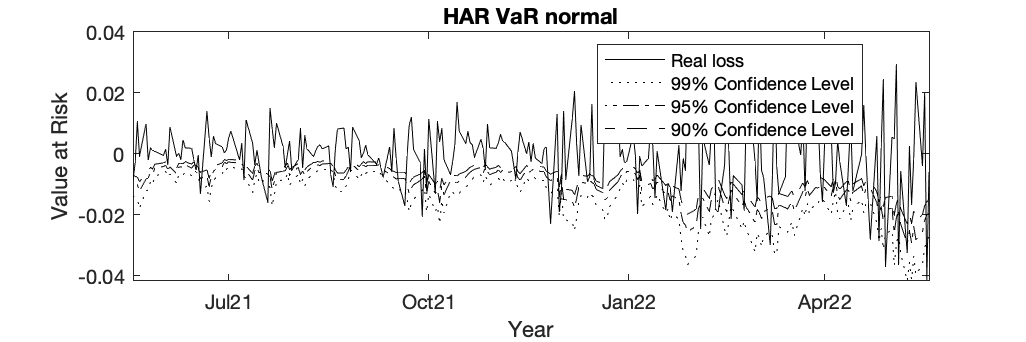

Model_Name='HAR';
ftxt=fopen(SaveTxtName,'a+');
fprintf(ftxt,'\n');
fprintf(ftxt,[Model_Name,' & ']);
line2latex(Output_HAR.Table_t(3,:),ftxt)
fclose(ftxt);
figureVaR(Output_HAR.VaR_normal(:,FigureVaRIndex),logRet,TimeLine);
title([Model_Name,' VaR normal'])
set(gcf,'Position',[500 500 900 300]);
saveas(gcf,[results_folder,'/VaR_',Model_Name,'_t.png'])

## CPHAR t VaR

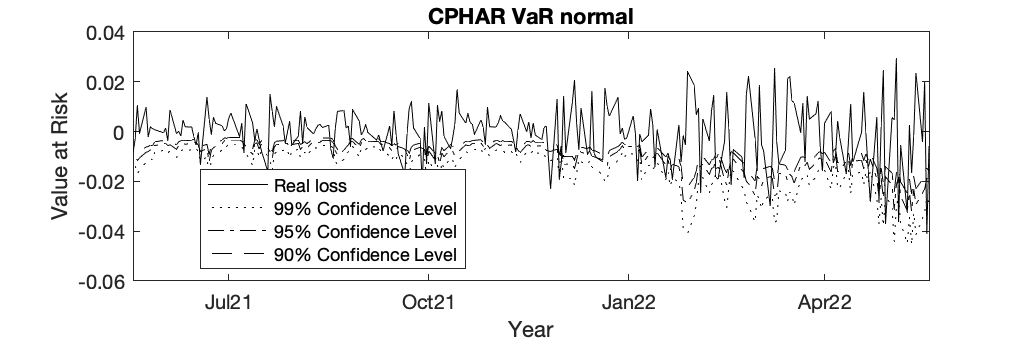

Model_Name='CPHAR';
ftxt=fopen(SaveTxtName,'a+');
fprintf(ftxt,'\n');
fprintf(ftxt,[Model_Name,' & ']);
line2latex(Output_CPHAR.Table_t(3,:),ftxt)
fclose(ftxt);
figureVaR(Output_CPHAR.VaR_normal(:,FigureVaRIndex),logRet,TimeLine);
title([Model_Name,' VaR normal'])
set(gcf,'Position',[500 500 900 300]);
saveas(gcf,[results_folder,'/VaR_',Model_Name,'_t.png'])

## CPHARiteration t VaR

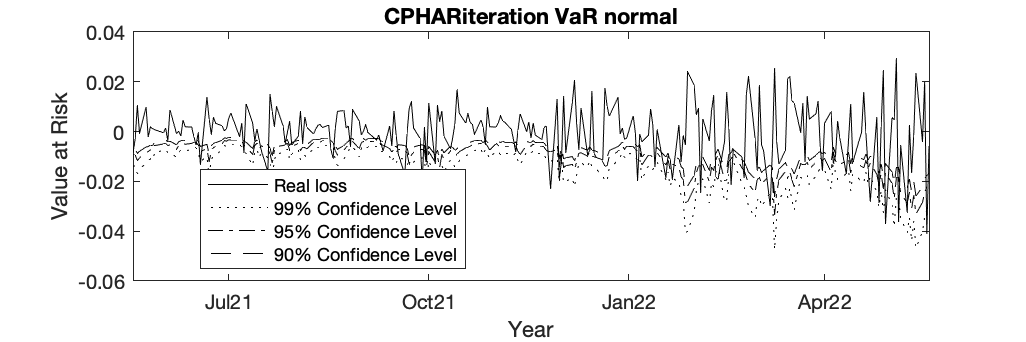

Model_Name='CPHARiteration';
ftxt=fopen(SaveTxtName,'a+');
fprintf(ftxt,'\n');
fprintf(ftxt,[Model_Name,' & ']);
line2latex(Output_CPHARiteration.Table_t(3,:),ftxt)
fclose(ftxt);
figureVaR(Output_CPHARiteration.VaR_normal(:,FigureVaRIndex),logRet,TimeLine);
title([Model_Name,' VaR normal'])
set(gcf,'Position',[500 500 900 300]);
saveas(gcf,[results_folder,'/VaR_',Model_Name,'_t.png'])

## Closing the file

% Closing the file
ftxt=fopen(SaveTxtName,'a+');
fprintf(ftxt,'\\hline \n');
fprintf(ftxt,'\\end{tabular}');
fclose(ftxt);

## Figures of models with normal and t distribution

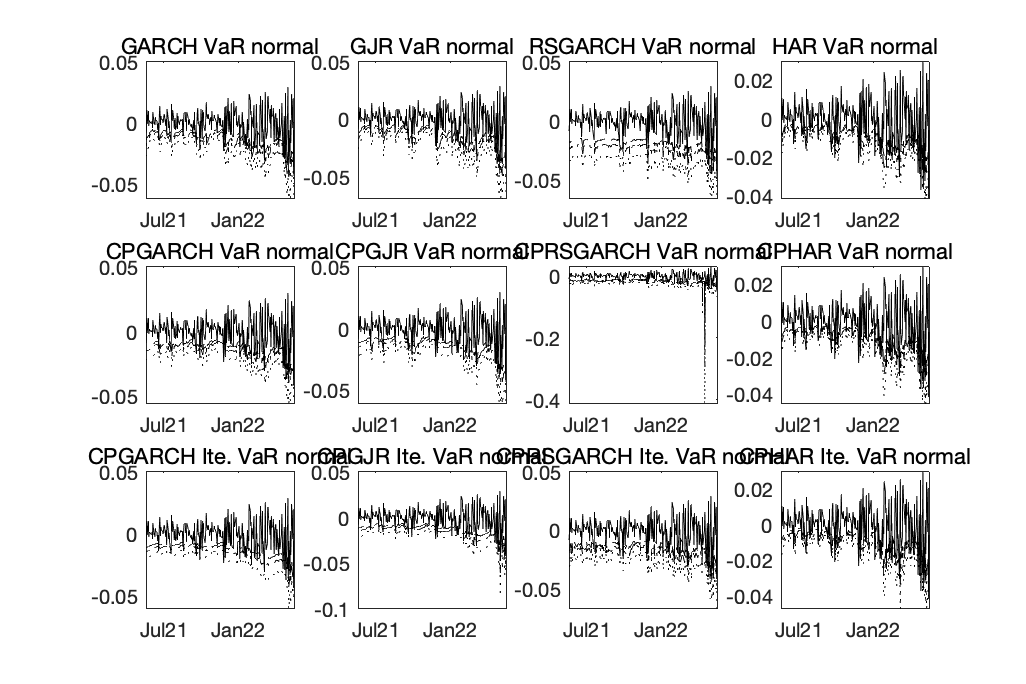

figure;
subplot(3,4,1);
figureVaR_small(Output_GARCH.VaR_normal(:,FigureVaRIndex),logRet,TimeLine);
subtitle(['GARCH',' VaR normal'])
subplot(3,4,2);
figureVaR_small(Output_GJR.VaR_normal(:,FigureVaRIndex),logRet,TimeLine);
subtitle(['GJR',' VaR normal'])
subplot(3,4,3);
figureVaR_small(Output_RSGARCH.VaR_normal(:,FigureVaRIndex),logRet,TimeLine);
subtitle(['RSGARCH',' VaR normal'])
subplot(3,4,4);
figureVaR_small(Output_HAR.VaR_normal(:,FigureVaRIndex),logRet,TimeLine);
subtitle(['HAR',' VaR normal'])
subplot(3,4,5);
figureVaR_small(Output_CPGARCH.VaR_normal(:,FigureVaRIndex),logRet,TimeLine);
subtitle(['CPGARCH',' VaR normal'])
subplot(3,4,6);
figureVaR_small(Output_CPGJR.VaR_normal(:,FigureVaRIndex),logRet,TimeLine);
subtitle(['CPGJR',' VaR normal'])
subplot(3,4,7);
figureVaR_small(Output_CPRSGARCH.VaR_normal(:,FigureVaRIndex),logRet,TimeLine);
subtitle(['CPRSGARCH',' VaR normal'])
subplot(3,4,8);
figureVaR_small(Output_CPHAR.VaR_normal(:,FigureVaRIndex),logRet,TimeLine);
subtitle(['CPHAR',' VaR normal'])
subplot(3,4,9);
figureVaR_small(Output_CPGARCHiteration.VaR_normal(:,FigureVaRIndex),logRet,TimeLine);
subtitle(['CPGARCH Ite.',' VaR normal'])
subplot(3,4,10);
figureVaR_small(Output_CPGJRiteration.VaR_normal(:,FigureVaRIndex),logRet,TimeLine);
subtitle(['CPGJR Ite.',' VaR normal'])
subplot(3,4,11);
figureVaR_small(Output_CPRSGARCHiteration.VaR_normal(:,FigureVaRIndex),logRet,TimeLine);
subtitle(['CPRSGARCH Ite.',' VaR normal'])
subplot(3,4,12);
figureVaR_small(Output_CPHARiteration.VaR_normal(:,FigureVaRIndex),logRet,TimeLine);
subtitle(['CPHAR Ite.',' VaR normal'])
set(gcf,'Position',[500 500 900 600]);
saveas(gcf,[results_folder,'/VaR_allmodel_normal.png'])

## Figures of models with t distribution

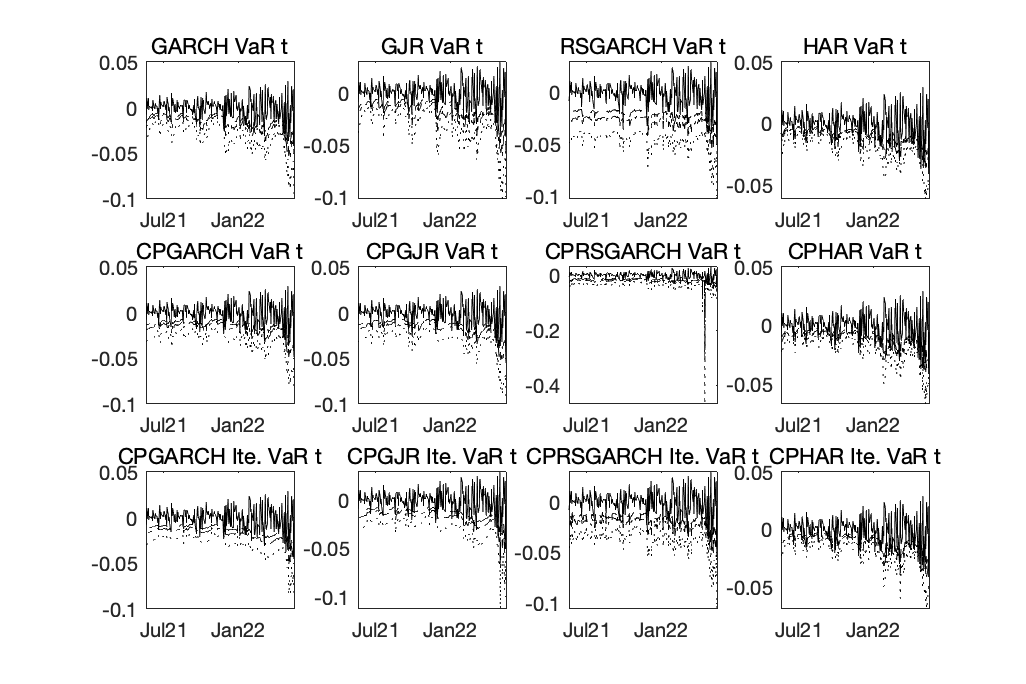

figure;
subplot(3,4,1);
figureVaR_small(Output_GARCH.VaR_t(:,FigureVaRIndex),logRet,TimeLine);
subtitle(['GARCH',' VaR t'])
subplot(3,4,2);
figureVaR_small(Output_GJR.VaR_t(:,FigureVaRIndex),logRet,TimeLine);
subtitle(['GJR',' VaR t'])
subplot(3,4,3);
figureVaR_small(Output_RSGARCH.VaR_t(:,FigureVaRIndex),logRet,TimeLine);
subtitle(['RSGARCH',' VaR t'])
subplot(3,4,4);
figureVaR_small(Output_HAR.VaR_t(:,FigureVaRIndex),logRet,TimeLine);
subtitle(['HAR',' VaR t'])
subplot(3,4,5);
figureVaR_small(Output_CPGARCH.VaR_t(:,FigureVaRIndex),logRet,TimeLine);
subtitle(['CPGARCH',' VaR t'])
subplot(3,4,6);
figureVaR_small(Output_CPGJR.VaR_t(:,FigureVaRIndex),logRet,TimeLine);
subtitle(['CPGJR',' VaR t'])
subplot(3,4,7);
figureVaR_small(Output_CPRSGARCH.VaR_t(:,FigureVaRIndex),logRet,TimeLine);
subtitle(['CPRSGARCH',' VaR t'])
subplot(3,4,8);
figureVaR_small(Output_CPHAR.VaR_t(:,FigureVaRIndex),logRet,TimeLine);
subtitle(['CPHAR',' VaR t'])
subplot(3,4,9);
figureVaR_small(Output_CPGARCHiteration.VaR_t(:,FigureVaRIndex),logRet,TimeLine);
subtitle(['CPGARCH Ite.',' VaR t'])
subplot(3,4,10);
figureVaR_small(Output_CPGJRiteration.VaR_t(:,FigureVaRIndex),logRet,TimeLine);
subtitle(['CPGJR Ite.',' VaR t'])
subplot(3,4,11);
figureVaR_small(Output_CPRSGARCHiteration.VaR_t(:,FigureVaRIndex),logRet,TimeLine);
subtitle(['CPRSGARCH Ite.',' VaR t'])
subplot(3,4,12);
figureVaR_small(Output_CPHARiteration.VaR_t(:,FigureVaRIndex),logRet,TimeLine);
subtitle(['CPHAR Ite.',' VaR t'])
set(gcf,'Position',[500 500 900 600]);
saveas(gcf,[results_folder,'/VaR_allmodel_t.png'])

## Functions

function figureVaR(VaR,ret,TimeLine)
figure;
plot(TimeLine, ret, 'k' )
hold on 
plot(TimeLine, VaR(:,1), 'k:')
hold on 
plot(TimeLine, VaR(:,2),'k-.')
hold on 
plot(TimeLine, VaR(:,3),'k--')
xlim([TimeLine(1),TimeLine(end)])
xlabel('Year')
ylabel('Value at Risk')
% str1 = 'VaR Estimation by Volatility Structural Change Model with K=';
% str2 = num2str(K);
% MakeTitle = strcat(str1,str2);
% title(MakeTitle)
legend('Real loss','99% Confidence Level','95% Confidence Level','90% Confidence Level','Location', 'best')
dateaxis('x' , 12)
set(gcf,'Position',[500 500 900 300]);
end

function figureVaR_small(VaR,ret,TimeLine)
plot(TimeLine, ret, 'k' )
hold on 
plot(TimeLine, VaR(:,1), 'k:')
hold on 
plot(TimeLine, VaR(:,2),'k-.')
hold on 
plot(TimeLine, VaR(:,3),'k--')
xlim([TimeLine(1),TimeLine(end)])
%xlabel('Year')
%ylabel('Value at Risk')
% str1 = 'VaR Estimation by Volatility Structural Change Model with K=';
% str2 = num2str(K);
% MakeTitle = strcat(str1,str2);
% title(MakeTitle)
%legend('Real loss','99% Confidence Level','95% Confidence Level','90% Confidence Level','Location', 'best')
dateaxis('x' , 12)
%set(gcf,'Position',[500 500 900 300]);
end

LR statistic符合自由度为1的卡方分布

x:失败天数；

n：总天数；

p_star:null pypothesis failure rate；

LR = 2 * log( ( (1-x./n).^(n-x).*(x/n).^x) )...

        -2 * log( ( (1-p_star).^(n-x).*(p_star).^x) );

function line2latex(T,SaveTxtName)
    
    % Error detection and default parameters
    if nargin < 1, error('Not enough parameters.'); end
    
    % Parameters
    n_row = size(T,1);
    n_col = size(T,2);

    % Writing the data
    try
        for row = 1:n_row
            temp{1,n_col} = [];
            for col = 1:n_col
                value = T{row,col};
                if isstruct(value), error('Table must not contain structs.'), end
                while iscell(value), value = value{1,1}; end
                if isinf(value), value = '$\infty$'; end
                temp{1,col} = num2str(value);
                if value>chi2inv(0.99,1),temp{1,col} = ['\textbf{',num2str(value),'}$^{***}$'];
                elseif value>chi2inv(0.95,1),temp{1,col} = ['\textbf{',num2str(value),'}$^{**}$'];
                elseif value>chi2inv(0.9,1),temp{1,col} = ['\textbf{',num2str(value),'}$^{*}$'];
                else temp{1,col} = num2str(value);
                end
            end
            fprintf(SaveTxtName,'%s \\\\ \n', strjoin(temp, ' & '));
            clear temp;
        end
    catch
        error('Unknown error. Make sure that table only contains chars, strings or numeric values.');
    end
end

function LR  = LR_PF(x,n,p_star )
LR = 2 * log( ( ((1-x./n)/(1-p_star)).^(n-x) .* (x/n/p_star).^x) );
end

Report table and figure of VaR

function Output=report_VaR(vf,logRet,TimeLine,ConfidenceLevel,D,forecast_index,FigureVaRIndex,SaveTxtName,Model_Name)
VaR_normal = zeros(size(logRet,1),length(ConfidenceLevel));
VaR_t = zeros(size(logRet,1),length(ConfidenceLevel));
T=length(vf);
for i = 1 : T
    historic_return = D.Return(find(forecast_index,1)+i-251:find(forecast_index,1)+i-2);
    % innovation normal distributed
    VaR_normal(i, :) = norminv(ConfidenceLevel,mean(historic_return),sqrt(vf(i)));    
    % innovation student-t distributed
    fit_data=fitdist(historic_return,"tLocationScale");
    VaR_t(i, :) = tinv(ConfidenceLevel,fit_data.nu)*sqrt(vf(i))+mean(historic_return);
end
Table_normal=tableVaRPredict(VaR_normal,logRet,ConfidenceLevel);
% figureVaR(VaR_normal(:,FigureVaRIndex),logRet,TimeLine);
% title([Model_Name,' VaR normal'])

Table_t=tableVaRPredict(VaR_t,logRet,ConfidenceLevel);
% figureVaR(VaR_t(:,FigureVaRIndex),logRet,TimeLine);
% title([Model_Name,' VaR student-t'])

Output.Table_normal=Table_normal;
Output.Table_t=Table_t;
Output.VaR_normal=VaR_normal;
Output.VaR_t=VaR_t;

end

To generate table which reports Kupiec test of VaR estimate

function [TableOutput,ConfidenceLevel_Label]=tableVaRPredict(VaRPredict,logRet,ConfidenceLevel)
format short
switch nargin
    case 2
        ConfidenceLevel = 0.05;
end
outsampleSize=numel(logRet);
% make label of table
Confidence_Length=numel(ConfidenceLevel);
ConfidenceLevel_Label=cell(1,Confidence_Length);
ConfidenceLevel=reshape(ConfidenceLevel,Confidence_Length,1);
for i=1:Confidence_Length
    ConfidenceLevel_Label{1,i}=['CL',num2str(ConfidenceLevel(i))];
end
% Kupiec_Test=zeros(size(ConfidenceLevel));
% Kupiec_Test_Significance=zeros(size(ConfidenceLevel));
% Count_Failure=zeros(size(ConfidenceLevel));
% for i = 1:Confidence_Length
%     Count_Failure(i)=sum(VaRPredict(:,i)>logRet);
%     Kupiec_Test(i)=roundn(LR_PF(Count_Failure(i),outsampleSize,ConfidenceLevel(i)),-2);
%     Kupiec_Test_Significance(i)=chi2cdf(Kupiec_Test(i),1);
% end
% TableOutput=table([ConfidenceLevel,Count_Failure,Kupiec_Test,Kupiec_Test_Significance]', ...
%     'RowNames',{'Confidence level','Failures','Kupiec Test','Significance'});
TableOutput=zeros(3,length(ConfidenceLevel));
for i = 1:Confidence_Length
    TableOutput(1,i)=ConfidenceLevel(i);
    TableOutput(2,i)=sum(VaRPredict(:,i)>logRet);
    TableOutput(3,i)=roundn(LR_PF(TableOutput(2,i),outsampleSize,TableOutput(1,i)),-2);
    TableOutput(4,i)=chi2cdf(TableOutput(3,i),1);  
end
TableOutput=array2table(TableOutput,'RowNames',{'Confidence level','Failures','Kupiec Test','Significance'},'VariableNames',ConfidenceLevel_Label);
end